 **1. Analiza typu hotelu – czy wybór hotelu wpływa na cenę i liczbę anulacji?**

Wczytanie danych


filename = 'hotel_bookings.csv';
T = readtable(filename);

Zadanie 2.

filename = 'hotel_bookings.csv';
T = readtable(filename);  

T.reservation_status_date = datetime(T.reservation_status_date, 'InputFormat', 'yyyy-MM-dd');

TT = table2timetable(T(:, {'adr', 'is_canceled'}), 'RowTimes', T.reservation_status_date);

TT_monthly = retime(TT, 'monthly', 'mean');
TT_monthly = round(TT_monthly, 2);

high_cancel = rowfun(@(x) x > 0.5, TT_monthly, 'InputVariables', 'is_canceled');

disp(TT_monthly(1:20, :))

       Time        adr      is_canceled
    __________    ______    ___________

    2014-10-01      62.8          1    
    2014-11-01         0          1    
    2014-12-01       NaN        NaN    
    2015-01-01     58.94          1    
    2015-02-01    102.93          1    
    2015-03-01     80.35          1    
    2015-04-01     97.54          1    
    2015-05-01     89.88          1    
    2015-06-01     89.39          1    
    2015-07-01     91.65       0.63    
    2015-08-01    113.32       0.32    
    2015-09-01    100.34       0.26    
    2015-10-01      75.9       0.42    
    2015-11-01     67.29       0.35    
    2015-12

Zadanie 3.

T.total_stay_nights = T.stays_in_week_nights + T.stays_in_weekend_nights;

total_guests = T.adults + T.children + T.babies;
total_guests(total_guests == 0) = 1;  
T.adr_per_person = round(T.adr ./ total_guests, 2);

disp(T(1:10, {'stays_in_week_nights', 'stays_in_weekend_nights', ...
              'total_stay_nights', 'adr', 'adr_per_person',}))

    stays_in_week_nights    stays_in_weekend_nights    total_stay_nights     adr     adr_per_person
    ____________________    _______________________    _________________    _____    ______________

             0                         0                       0                0            0     
             0                         0                       0                0            0     
             1                         0                       1               75           75     
             1                         0                       1               75           75     
             2                         0                       2               98           49     
             2                         0                       2               98           49     
             2               

Zadanie 4.

colsToRemove = {'agent', 'company', 'reservation_status_date'};
colsToRemove = colsToRemove(ismember(colsToRemove, T.Properties.VariableNames));
T = removevars(T, colsToRemove);

disp("Kolumny po removevars:");

Kolumny po removevars:


disp(T.Properties.VariableNames')

    {'hotel'                         }
    {'is_canceled'                   }
    {'lead_time'                     }
    {'arrival_date_year'             }
    {'arrival_date_month'            }
    {'arrival_date_week_number'      }
    {'arrival_date_day_of_month'     }
    {'stays_in_weekend_nights'       }
    {'stays_in_week_nights'          }
    {'adults'                        }
    {'children'                      }
    {'babies'                        }
    {'meal'                          }
    {'country'                       }
    {'market_segment'                }
    {'distribution_channel'          }
    {'is_repeated_guest'             }
    {'previous_cancellations'        }
    {'previous_bookings_not_canceled'}
    {'reserved_room_type'            }
    {'assigned_room_type'            }
    {'booking_changes'               }
    {'deposit_type'                  }
    {'days_in_waiting_list'          }
    {'customer_type'                 }
    {'adr'               


T = movevars(T, 'adr_per_person', 'After', 'adr');

disp("Fragment tabeli po movevars:");

Fragment tabeli po movevars:


disp(T(1:5, {'adr', 'adr_per_person'}))

    adr    adr_per_person
    ___    ______________

     0            0      
     0            0      
    75           75      
    75           75      
    98           49      




T.meal = categorical(T.meal);
T.meal = mergecats(T.meal, {'Undefined', 'SC'});

disp("Kategorie 'meal' po mergecats:");

Kategorie 'meal' po mergecats:


disp(categories(T.meal))

    {'BB'       }
    {'FB'       }
    {'HB'       }
    {'Undefined'}



Zadanie 5.

missingBefore = sum(ismissing(T), 'all');

T.children = fillmissing(T.children, 'constant', 0);

T.lead_time = fillmissing(T.lead_time, 'movmedian', 5);

T = rmmissing(T, 'DataVariables', 'country');

missingAfter = sum(ismissing(T), 'all');
fprintf("Liczba braków przed: %d, po: %d\n", missingBefore, missingAfter);

Liczba braków przed: 8, po: 4


Zadanie 6.

out_adr = isoutlier(T.adr);
out_guests = isoutlier(T.adults + T.children + T.babies);

fprintf("Liczba outlierów w adr: %d\n", sum(out_adr));
fprintf("Liczba outlierów w liczbie osób: %d\n", sum(out_guests));

T.adr = filloutliers(T.adr, 'center', 'movmedian', 5);

T = rmoutliers(T, 'DataVariables', {'adults', 'children', 'babies'});

Zadanie 7.

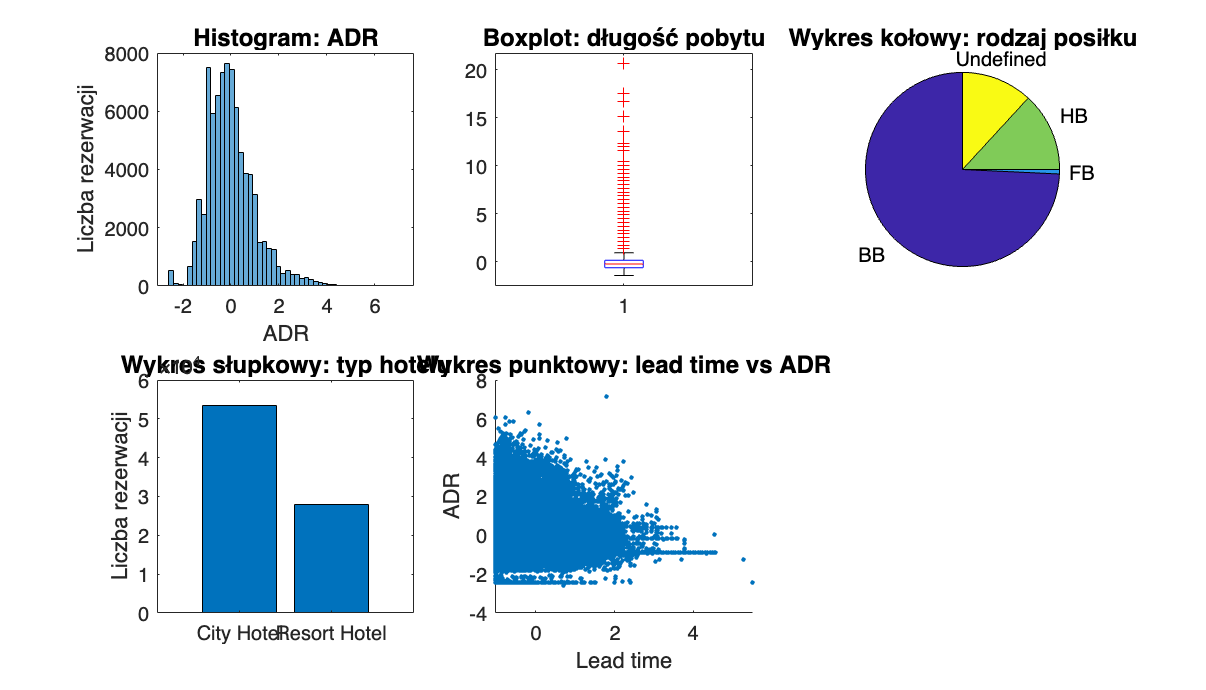

figure('Position', [100, 100, 1400, 800])

subplot(2,3,1)
histogram(T.adr, 50)
title('Histogram: ADR', 'FontSize', 12)
xlabel('ADR'), ylabel('Liczba rezerwacji')

subplot(2,3,2)
boxplot(T.total_stay_nights)
title('Boxplot: długość pobytu', 'FontSize', 12)

subplot(2,3,3)
meal_counts = countcats(categorical(T.meal));
labels = categories(categorical(T.meal));
pie(meal_counts, labels)
title('Wykres kołowy: rodzaj posiłku', 'FontSize', 12)

subplot(2,3,4)
hotel_counts = countcats(categorical(T.hotel));
bar(categorical(categories(categorical(T.hotel))), hotel_counts)
title('Wykres słupkowy: typ hotelu', 'FontSize', 12)
ylabel('Liczba rezerwacji')

subplot(2,3,5)
scatter(T.lead_time, T.adr, 5, 'filled')
xlabel('Lead time'), ylabel('ADR')
title('Wykres punktowy: lead time vs ADR', 'FontSize', 12)

Zadanie 8.

varsToNormalize = {'lead_time', 'adr', 'total_stay_nights'};
T(:, varsToNormalize) = varfun(@normalize, T, 'InputVariables', varsToNormalize);

disp('Dane kategoryczne (np. meal, hotel) nie są normalizowane – nie mają sensu liczbowego.')

Dane kategoryczne (np. meal, hotel) nie są normalizowane – nie mają sensu liczbowego.


Zadanie 9.

save('hotel_data_processed.mat', 'T')
